# MAZE Solver using SARSA Learning

## Initailization

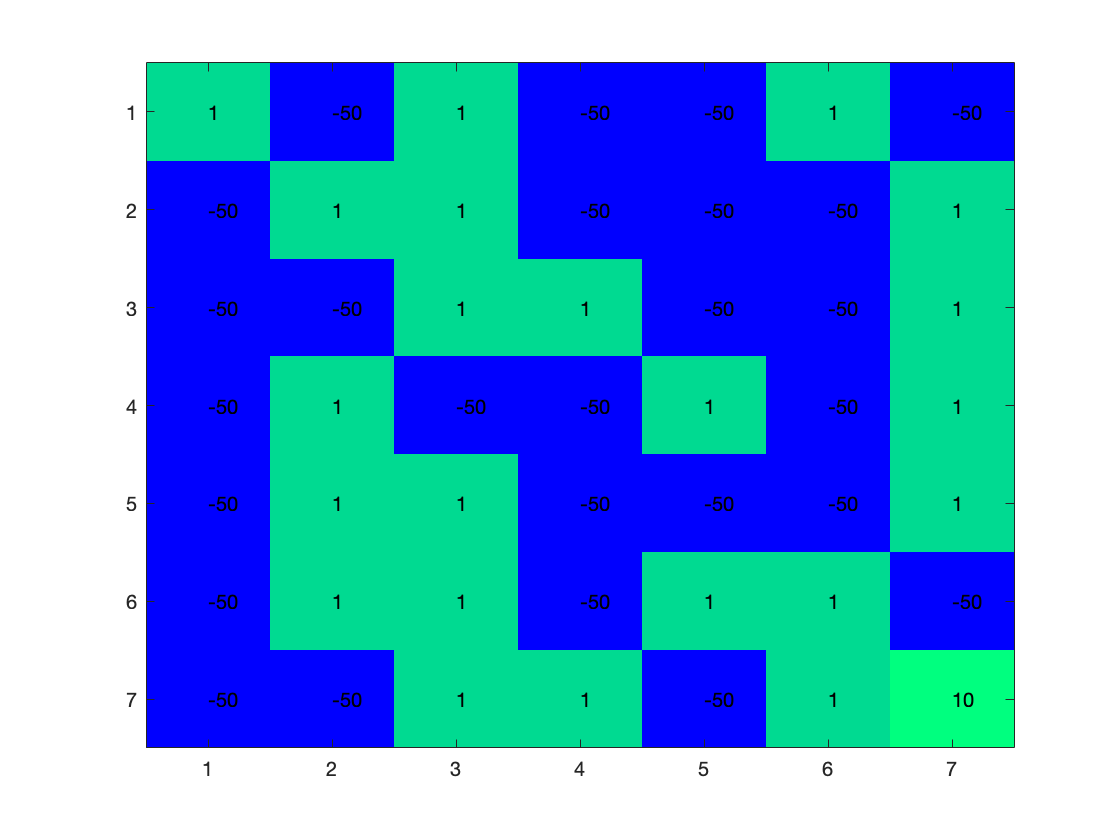

clear all;clc;
load('maze7x7.mat');
figure
matrixPlot(maze)

## Plotting Environment of the maze, dimensions of maze : 7x7 (i.e, n = 7)

- Starting Position is (1,1)

- Goal is to reach (7,7)

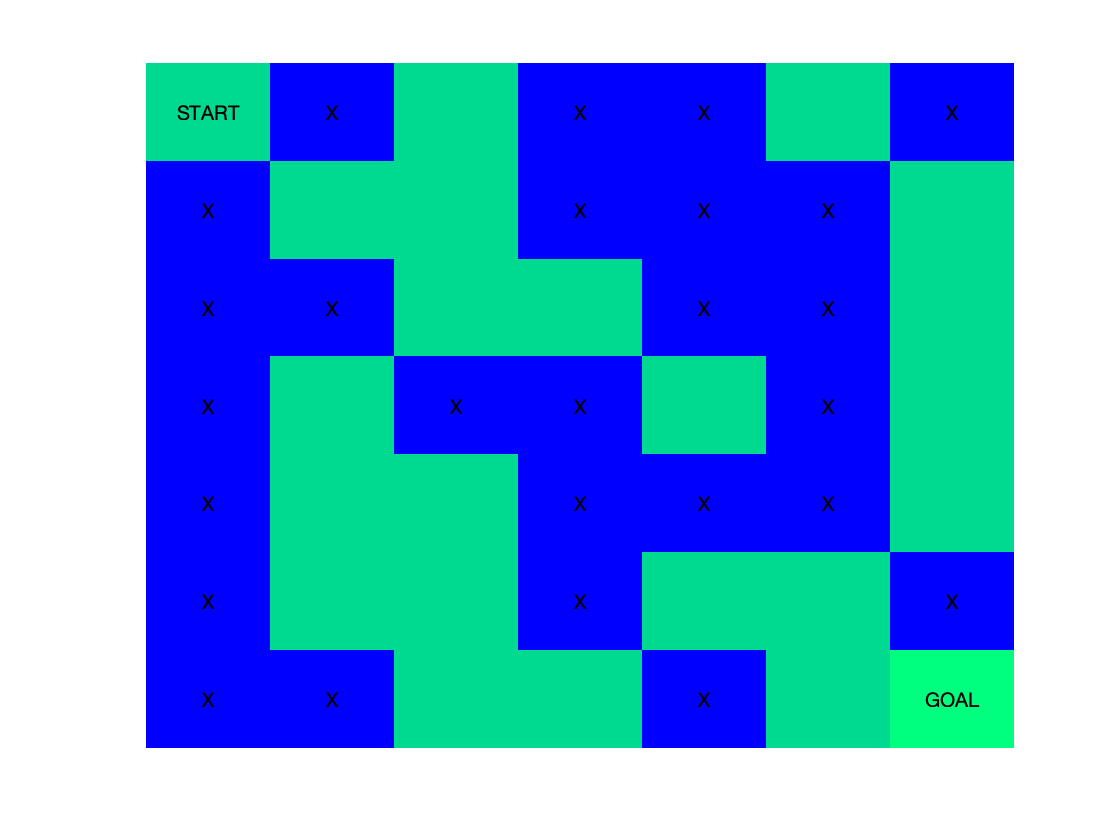

mazeSize = length(maze);

plotDimensionsOfMaze(mazeSize)

Goal=mazeSize*mazeSize;

Goal State is: 49

fprintf('Goal State is: %d',Goal)

## Creating Reward Matrix for the Maze 

Possible actions are:

- Up     (i-n)

- Down   (i+n)

- Left   (i-1)

- Right  (i+1)

- Diagonally SE (i+n+1)

- Diagonally SW (i+n-1)

- Diagonally NE (i-n+1)

- Diagonally NW (i-n-1)

Reward  is -Inf (~No reward) for any other actions. Thus any other action other then above action will not occur.

reward=[];

for row=1:Goal
    reward=[reward;reshape(maze',1,Goal);];
end

for row=1:Goal
    for column=1:Goal
        if column~=row-mazeSize && column~=row+mazeSize && column~=row-1 && column~=row+1 && column~=row+mazeSize+1 && column~=row+mazeSize-1 && column~=row-mazeSize+1 && column~=row-mazeSize-1
            reward(row,column)=-Inf;
        end
    end
end

## SARSA algorithm

- Initialize the Q-matrix.

- Setting the goal state to be 'n*n'. 

- Gamma=0.5 and alpha=0.4 (Selected after several runs)

- Maximum number of iterations (for convergence)

q=zeros(size(reward));
gamma=0.5; alpha=0.4; maxItr=100;


- Repeat until Convergence OR Maximum Iterations

- cs => current state

- ns => next state

for row=1:maxItr
    
    % Starting from any Random state
    cs=randi([1 length(reward)],1,1);
    
    % Repeate until Goal state is reached
    while(1)
        
        % Possible Actions from current state
        actions=find(reward(cs,:)>0);
        
        % Next State due to possible actions
        ns=actions(randi([1 length(actions)]));
        
        % Possible Actions from Next State
        actions=find(reward(ns,:)>0);
        
        % q value, for action is choosen randomly from all possible actions
        randq=q(ns,actions(randi([1,length(actions)])));
        
        % Updation of Action-Value Function (SARSA)
        q(cs,ns)=q(cs,ns)+alpha*(reward(cs,ns)+gamma*randq -q(cs,ns));
        
        % Break, if Goal state is reached
        if(cs == Goal)
            break;
        end
        
        % Else Current-state is Next-State
        cs=ns;
    end
end

## Solving the maze i.e, finding a path (optimal) from START to GOAL

- Starting from the first postion

start=1;move=0;
path=[start];

- Iterating until Goal-State is reached

while(move~=Goal)
    [~,move]=max(q(start,:));
    
    % Deleting chances of getting stuck in small loops
    if ismember(move,path)
        [~,x]=sort(q(start,:),'descend');
        move=x(2);
        if ismember(move,path)
            [~,x]=sort(q(start,:),'descend');
            move=x(3);
        end
    end
    
    % Appending next action/move to the path
    path=[path,move]
    start=move;
end

path =      1     9


path =      1     9    10


path =      1     9    10    17


path =      1     9    10    17    23


path =      1     9    10    17    23    31


path =      1     9    10    17    23    31    38


path =      1     9    10    17    23    31    38    46


path =      1     9    10    17    23    31    38    46    40


path =      1     9    10    17    23    31    38    46    40    48


path =      1     9    10    17    23    31    38    46    40    48    49


## Solution of maze i.e, Optimal Path between START to GOAL

fprintf('Final Path: %s',num2str(path))

Final Path: 1   9  10  17  23  31  38  46  40  48  49


pmat=zeros(mazeSize,mazeSize);

[q, r]=quorem(sym(path),sym(mazeSize));
q=double(q+1);r=double(r);
q(r==0)=mazeSize;r(r==0)=mazeSize;

for row=1:length(q)
    pmat(q(row),r(row))=50;
end

## Final Plot of the maze

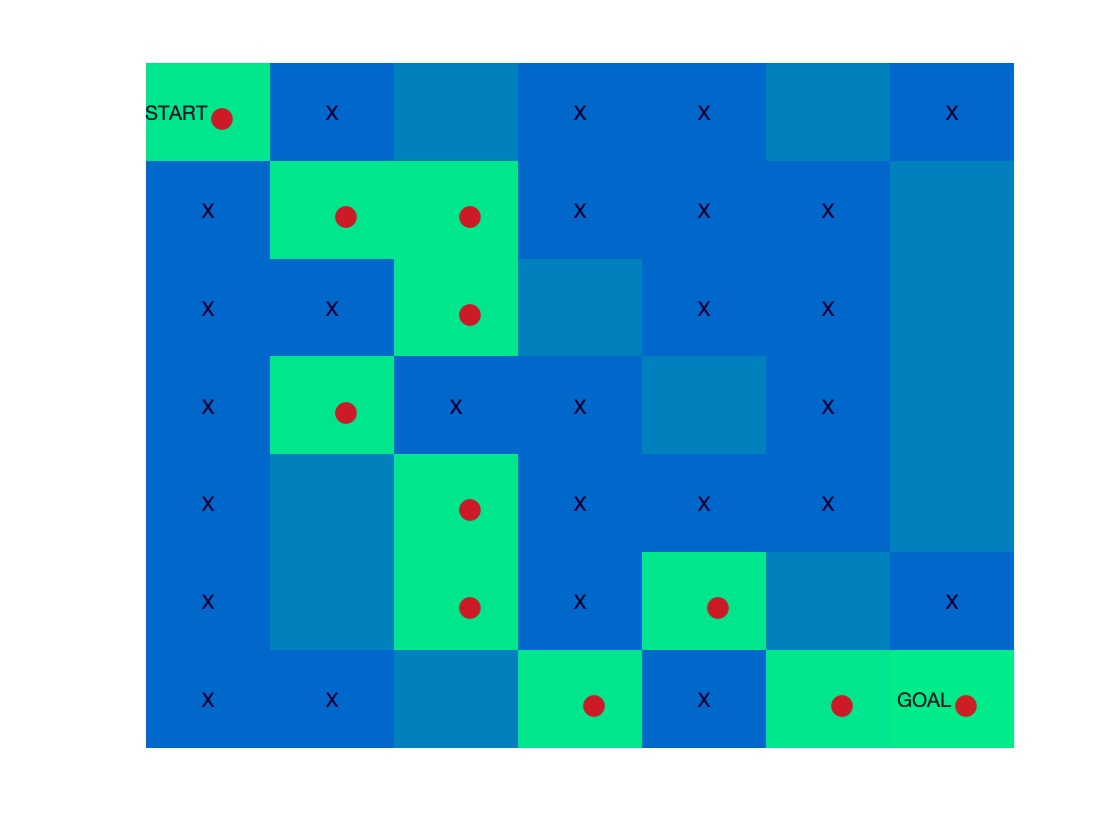

figure
imagesc(pmat)
colormap(white)

for row=1:mazeSize
    for column=1:mazeSize
        if maze(row,column)==min(maze)
            text(column,row,'X','HorizontalAlignment','center')
        end
        if pmat(row,column)==50
            text(column,row,'\bullet','Color','red','FontSize',28)
        end
    end
end
text(1,1,'START','HorizontalAlignment','right')
text(mazeSize,mazeSize,'GOAL','HorizontalAlignment','right')

hold on
imagesc(maze,'AlphaData',0.2)
colormap(winter)
hold off
axis off

% created by- Bhartendu, Machine Learning & Computing


### Functions

% % Plots

% Plotting Environment of the maze, dimensions of maze

function plotDimensionsOfMaze(mazeSize)
    
    figure
    imagesc(maze)
    colormap(winter)
    
    for row = 1:mazeSize
        for column = 1:mazeSize
            if maze(row,column) == min(maze)
                text(column,row, 'X', 'HorizontalAlignment', 'center')
            end
        end
    end
    text(1,1,'START','HorizontalAlignment','center')
    text(mazeSize, mazeSize, 'GOAL', 'HorizontalAlignment', 'center')
    
    axis off
end